# Solving Laplace Equations with a Combined BEM and PINN Approachclc

clc
clear

## **Constructing a 2D Point Grid over a Rectangular Domain**

% Number of points along each boundary
N_points_boundary = 101; % 101
% Create a linearly spaced vector from 0 to 1 with N_points_boundary points
lineargrid_y = linspace(0, 1, N_points_boundary);

% Generate a uniform grid for x-axis such that points are denser near x = 0 and sparser near x = 0.5
nonuniform_x = linspace(0,1,N_points_boundary);
% Capture the middle point in the nonuniform_x vector
inner_half = nonuniform_x(ceil(N_points_boundary/2));
% Declare a global variable for half the number of points along the boundary
global N_half_points_boundary
% Compute half the number of points along the boundary (excluding the middle point)
N_half_points_boundary = (N_points_boundary-1)/2;
% Compute the grid spacing as the difference between the first two points in lineargrid
global dx
dx = diff(nonuniform_x(1:2));
% Generate a 2D grid of points using nonuniform_x for x-axis and lineargrid_y for y-axis
[X, Y] = meshgrid(nonuniform_x, lineargrid_y);
% Reshape these grid points into a single 2 x N_points_boundary^2 array where each row is a coordinate pair
XY = [X(:), Y(:)];
% Clear the X and Y variables from memory to save space
clear X Y
% Randomly shuffle the rows of XY to randomize the order of the points
XY = XY(randperm(N_points_boundary^2), :);
% Remove points from XY that are in the top right quarter, creating an L-shaped region
XY(XY(:, 1) > 0.5, :) = [];

## Extracting Boundary and Inner Boundary Points

% Extract points from XY that lie on the bottom boundary (y = 0) and 
% within the left half (0 < x <= 0.5), representing the bottom boundary conditions
XY_bottom_BC = XY(XY(:,2)==0 & XY(:,1)<= .5 & XY(:,1)> 0, :);

% Extract points from XY that lie on the top boundary (y = 1) and 
% within the left half (x < 0.5), representing the top boundary conditions
XY_top_BC    = XY(XY(:,2)==1 & XY(:,1)< .5, :);

% Extract points from XY that lie on the left boundary (x = 0) and 
% below the top boundary (y < 1), representing the left boundary conditions
XY_left_BC   = XY(XY(:,1)==0 & XY(:,2)< 1, :);

% Extract points from XY that lie on the right boundary of the top left quarter 
% (x = 0.5) and above the midpoint (y > 0.5), representing the right top boundary conditions
XY_right_top_BC = XY(XY(:,1)==.5 & XY(:,2)>.5, :);

shift = dx;

% Extract Material Boundary
XY_Interface1 =  XY(XY(:,1) == inner_half - shift & XY(:,2) >=  dx & XY(:,2) < 0.5 ,:); % Material boundary points
XY_Material_Boundary =  XY(XY(:,1) == inner_half & XY(:,2) >=  dx & XY(:,2) < 0.5 ,:); % Material boundary points
XY_Interface2 =  XY(XY(:,1) == inner_half  & XY(:,2) >=  dx & XY(:,2) < 0.5 ,:); % Material boundary points

% Compute the boundary coordinates (BEM) using the custom function 'coordin' with specified parameters
% 'side' indicates the boundary sides
[boundaryCoords, ~, ~, side] = coordin(N_half_points_boundary, N_half_points_boundary, [.75; 0.25], 0.5, 0.5);

% Extract the boundary coordinates for the right bottom side (side == 4) and transpose them
XY_right_bottom_BC = boundaryCoords(:, side == 4)';


% Remove points from XY that are on the bottom boundary (y = 0)
XY(XY(:,2)==0, :) = [];

% Remove points from XY that are on the top boundary (y = 1)
XY(XY(:,2)==1, :) = [];

% Remove points from XY that are on the left boundary (x = 0)
XY(XY(:,1)==0, :) = [];

% Remove points from XY that are on the right boundary at x = 0.5
XY(XY(:,1)==.5, :) = [];

% Create a column vector of zeros with length N_points_boundary-1
full_zeros = zeros(N_points_boundary-1, 1);

% Create a column vector of zeros with length (N_points_boundary-1)/2
half_zeros = zeros((N_points_boundary-1)/2, 1);

% Create a column vector of ones with length (N_points_boundary-1)/2
half_ones = ones((N_points_boundary-1)/2, 1);

% Create a column vector of ones with length N_points_boundary-1
full_ones = ones(N_points_boundary-1, 1);

% Assign the right bottom boundary coordinates to XY_BEM_BC
XY_BEM_BC = XY_right_bottom_BC;

% Combine the boundary condition coordinates into a single array for Dirichlet boundary conditions
XY_BC_Dirichlet = [XY_left_BC; XY_bottom_BC; XY_right_top_BC; XY_BEM_BC];

% Create a corresponding array of boundary condition values for Dirichlet boundaries
U_BC_Dirichelt = [full_ones; half_ones; half_zeros; half_zeros];

% Assign the top boundary coordinates to XY_BC_Neumann for Neumann boundary conditions
XY_BC_Neumann = XY_top_BC;

% Create a corresponding array of boundary condition values for Neumann boundaries (all ones)
dU_BC_Neumann = half_ones;  % 0 means X direction, 1 means Y direction: the normal direction that should have zero derivative

% Declare a global variable XY_all and combine all points (interior and boundary)
global XY_all
XY_all = [XY; XY_BC_Dirichlet; XY_BC_Neumann];

## Visualization of Boundary and Inner Boundary Points

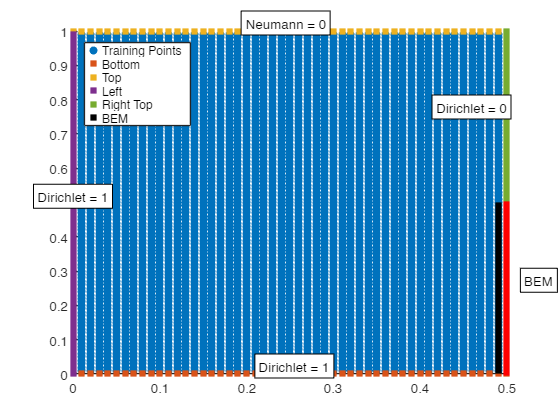


close all                % Close all open figure windows
clf                      % Clear current figure
hold on                  % Retain current plot and add new plots to it
% Allows subsequent plots to be added to the current figure without replacing the existing plots

scatter(XY(:,1),XY(:,2), 'filled') % Scatter plot of training points
% Plots the training points using their X and Y coordinates, with filled markers

scatter(XY_bottom_BC(:,1),XY_bottom_BC(:,2), 'filled', 'square') % Scatter plot of bottom boundary points
% Plots the bottom boundary points, using filled squares as markers

scatter(XY_top_BC(:,1),XY_top_BC(:,2), 'filled', 'square')       % Scatter plot of top boundary points
% Plots the top boundary points, using filled squares as markers

scatter(XY_left_BC(:,1),XY_left_BC(:,2), 'filled', 'square')     % Scatter plot of left boundary points
% Plots the left boundary points, using filled squares as markers

scatter(XY_right_top_BC(:,1),XY_right_top_BC(:,2), 'filled', 'square')   % Scatter plot of right top boundary points
% Plots the right top boundary points, using filled squares as markers

% scatter(XY_right_bottom_BC(:,1),XY_right_bottom_BC(:,2), 'filled', 'square') % Scatter plot of right bottom boundary points
% Plots the right bottom boundary points, using filled squares as markers

% Adding text labels near each set of boundary points
text(mean(XY_bottom_BC(:,1)), mean(XY_bottom_BC(:,2)), 'Dirichlet = 1', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', 'BackgroundColor', 'white','EdgeColor', 'black')
% Adds a text label "Dirichlet = 1" near the bottom boundary points

text(mean(XY_top_BC(:,1)), mean(XY_top_BC(:,2)), 'Neumann = 0', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', 'BackgroundColor', 'white','EdgeColor', 'black')
% Adds a text label "Neumann = 1" near the top boundary points

text(mean(XY_left_BC(:,1)), mean(XY_left_BC(:,2)), 'Dirichlet = 1', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center', 'BackgroundColor', 'white','EdgeColor', 'black')
% Adds a text label "Dirichlet = 1" near the left boundary points

text(mean(XY_right_top_BC(:,1)), mean(XY_right_top_BC(:,2)), 'Dirichlet = 0', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'BackgroundColor', 'white','EdgeColor', 'black')
% Adds a text label "Dirichlet = 0" near the right top boundary points

text(mean(XY_right_bottom_BC(:,1))+0.02, mean(XY_right_bottom_BC(:,2)), 'BEM', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left', 'BackgroundColor', 'white','EdgeColor', 'black')
% Adds a text label "BEM" near the right bottom boundary points

% Scatter plots for Material Boundary condition points with filled square markers
scatter(XY_Interface1(:,1), XY_Interface1(:,2), "square", 'filled','k') % Material Boundary points (Interface 1)
scatter(XY_Interface2(:,1), XY_Interface2(:,2), "square", 'filled','k') % Material Boundary points (Interface 2)

scatter(XY_BC_Dirichlet(end-N_half_points_boundary+1:end,1), XY_BC_Dirichlet(end-N_half_points_boundary+1:end,2), "square", 'filled','r') % Material Boundary points (Interface 2)

legend({'Training Points', 'Bottom', 'Top', 'Left', 'Right Top', 'BEM'}, 'Location', 'northwest') 

## Converting Boundary Conditions to Deep Learning array (dlarrays)

% Applying boundary conditions to dlarrays

% Convert XY_BC_Dirichlet to dlarray with "BC" label
XY_BC_Dirichlet = dlarray(XY_BC_Dirichlet, "BC");

% Convert XY_BC_Neumann to dlarray with "BC" label
XY_BC_Neumann = dlarray(XY_BC_Neumann, "BC");

% Convert U_BC_Dirichelt to dlarray with "BC" label
U_BC_Dirichelt = dlarray(U_BC_Dirichelt, "BC");

% Convert dU_BC_Neumann to dlarray with "BC" label
dU_BC_Neumann = dlarray(dU_BC_Neumann, "BC");

% Convert XY_all to dlarray with "BC" label
XY_all = dlarray(XY_all, "BC");

% Convert XY to dlarray with "BC" label
XY = dlarray(XY, "BC");

XY_Interface1 = dlarray(XY_Interface1, "BC");

XY_Interface2 = dlarray(XY_Interface2, "BC");

## **Training a PINN Model for the Left Subdomain**

minLayers = 9;
maxLayers = 9;
minNeurons = 100;
maxNeurons = 100;

% Number of random samples to test
numSamples = 1;

% Initialize variables to track the best configuration
bestLoss = inf;
bestConfig = struct();

% Arrays to store configuration details and corresponding losses
allConfigs = cell(numSamples, 1);
allLosses = zeros(numSamples, 1);

max_evals = 10000; % 4000

% Weights for Dirichlet and Neumann boundary condition losses
weight_Dir_Bc = 1;
weight_Neu_Bc = 1;
weight_Dir_Bc_BEM = 1;
weight_Interface_n_Bc = 1;
weight_Interface_t_Bc = 1;


% Loop through the number of samples
for sample = 1:numSamples
    % Randomly sample the number of layers and neurons
    numLayers = randi([minLayers, maxLayers]);
    numNeurons = randi([minNeurons, maxNeurons]);

    % Initialize the parameters for the network as a structure.
    parameters = struct;

    % Initialize the parameters for the first fully connected (fc) layer.
    sz = [numNeurons 2]; % Size of the weight matrix for the first fc layer: [number of neurons, number of input channels].
    parameters.fc1_Weights = initializeHe(sz, 2, "double"); % Initialize weights using He initialization.
    parameters.fc1_Bias = initializeZeros([numNeurons 1], "double"); % Initialize biases to zeros.

    % Initialize the parameters for each of the remaining intermediate fully connected layers.
    for layerNumber = 2:numLayers-1
        name = "fc" + layerNumber; % Generate the layer name dynamically (e.g., fc2, fc3, ...).

        sz = [numNeurons numNeurons]; % Size of the weight matrix for intermediate fc layers: [number of neurons, number of neurons].
        numIn = numNeurons; % Number of input channels for the current fc layer.
        parameters.(name + "_Weights") = initializeHe(sz, numIn, "double"); % Initialize weights using He initialization.
        parameters.(name + "_Bias") = initializeZeros([numNeurons 1], "double"); % Initialize biases to zeros.
    end

    % Initialize the parameters for the final fully connected layer.
    sz = [1 numNeurons]; % Size of the weight matrix for the final fc layer: [1, number of neurons].
    numIn = numNeurons; % Number of input channels for the final fc layer.
    parameters.("fc" + numLayers + "_Weights") = initializeHe(sz, numIn, "double"); % Initialize weights using He initialization.
    parameters.("fc" + numLayers + "_Bias") = initializeZeros([1 1], "double"); % Initialize biases to zeros.

    % Convert parameters struct to vector format
    global parameterNames parameterSizes
    [parametersV, parameterNames, parameterSizes] = parameterStructToVector(parameters);

    % Define an anonymous function for the objective function
    objFun = @(parameters) objectiveFunction(...
        parameters, ...                          % Input: parameters vector or structure
        XY, ...                                  % Input: XY data
        XY_BC_Dirichlet, ...                     % Input: XY_BC_Dirichlet data
        XY_BC_Neumann, ...                       % Input: XY_BC_Neumann data
        XY_Interface1,... 
        XY_Interface2,...
        U_BC_Dirichelt, ...                      % Input: U_BC_Dirichelt data
        dU_BC_Neumann, ...                       % Input: dU_BC_Neumann data
        parameterNames, ...                      % Input: parameterNames (assumed to be part of the objective function)
        parameterSizes,...
        weight_Dir_Bc,...
        weight_Neu_Bc,...
        weight_Dir_Bc_BEM, ...
        weight_Interface_n_Bc, ...
        weight_Interface_t_Bc);                         % Input: parameterSizes (assumed to be part of the objective function)

    % Set up initial parameters for optimization using fminunc
    if (isempty(gcp('nocreate')))
        parpool('Threads') % Create parallel pool using all available threads
    end

    options = optimoptions("fminunc", ...
        'HessianApproximation', "lbfgs", ... % Approximate Hessian using limited memory BFGS
        'MaxIterations', max_evals, ...      % Maximum number of iterations
        'MaxFunctionEvaluations', max_evals, ...  % Maximum number of function evaluations
        'OptimalityTolerance', 0, ...  % Optimality tolerance
        'SpecifyObjectiveGradient', true,...
        'UseParallel', true);%, ... % Specify gradient of the objective function
        % 'PlotFcn', { ...                      % Plot functions for visualization
        %     "optimplotfval", ...              % Plot function values
        %     @(x, optimValues, state) plotU2(x, optimValues, state, XY_all, parameterNames, parameterSizes), ... % Custom plot function
        %     @plotHistory_f, ...               % Plot history of objective function values
        %     @plotHistory_u, ...               % Plot history of parameter updates
        %     @plotHistory_du, ...              % Plot history of gradient updates
        %     @plotHistory_Energy ...           % Plot history of energy
        % }, ...
        % 'UseParallel', true);                 % Use parallel computing if available

    global history iter;

    history.loss = zeros(1, max_evals);     % Loss function values
    history.loss_f = zeros(1, max_evals);     % Loss function values
    history.loss_u = zeros(1, max_evals);     % Loss for u variables
    history.loss_du = zeros(1, max_evals);    % Loss for du variables
    history.loss_bem = zeros(1, max_evals);    % Loss for du variables
    % history.loss_energy = zeros(1, max_evals);% Energy loss values
    % history.loss_normal_interface = zeros(1, max_evals);% Energy loss values
    % history.loss_tangential_interface = zeros(1, max_evals);% Energy loss values    

    iter = 0;  % Iteration count

    parametersV = extractdata(parametersV);

    % Perform optimization using fminunc with specified objective function and options
    [parametersV, fval, exitflag, output] = fminunc(objFun, parametersV, options);

    % Store the current configuration and its loss
    allConfigs{sample} = struct('numLayers', numLayers, 'numNeurons', numNeurons, 'loss', fval);
    allLosses(sample) = fval;

    % Check if the current configuration is the best so far
    if fval < inf
        bestLoss = fval;
        bestConfig.numLayers = numLayers;
        bestConfig.numNeurons = numNeurons;
        bestConfig.parametersV = parametersV;
        bestConfig.parameterNames = parameterNames;
        bestConfig.parameterSizes = parameterSizes;
    end
end


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>



% % Plot the loss for each configuration
% figure;
% bar(allLosses);
% title('Loss for Different Configurations');
% xlabel('Configuration Number');
% ylabel('Loss');
% xticks(1:numSamples);
% xticklabels(cellfun(@(c) sprintf('L%d-N%d', c.numLayers, c.numNeurons), allConfigs, 'UniformOutput', false));
% xtickangle(45);
% grid on;

% Display the best configuration and its loss
disp("Best Configuration: Number of Layers: " + bestConfig.numLayers + ", Number of Neurons: " + bestConfig.numNeurons + ", Loss: " + bestLoss);

Best Configuration: Number of Layers: 9, Number of Neurons: 100, Loss: 0.00027436


% Use the best configuration for further evaluation or deployment
parametersV = bestConfig.parametersV;
parameterNames = bestConfig.parameterNames;
parameterSizes = bestConfig.parameterSizes;

## Evaluate the PINN Model 

% For prediction, convert the vector of parameters to a structure using the parameterVectorToStruct function (attached to this example as a supporting file).
parameters = parameterVectorToStruct(parametersV,parameterNames,parameterSizes);
% Use the full dataset as the test set
XY_test = XY_all;  
% Evaluate the model with the current parameters on the test set
U = model(parameters, XY_test);  
% Compute the total gradient of the objective function with respect to the parameters
du_tot = dlfeval(@gradient_calc_sum, parameters, XY_test);

#### **Function to Calculate the Gradient of the Sum of the Model Output with Respect to X**

function dU = gradient_calc_sum(parameters, X)
    % Calculate the gradient of the sum of the model output with respect to X
    dU = dlgradient(sum(model(parameters, X), "all"), X);
end

## **Saving Field and Scalar Potential**

X_test = extractdata(XY_test(1,:));
Y_test = extractdata(XY_test(2,:));
U_predicted = extractdata(U(1,:));
dUx_predicted = -extractdata(du_tot(1,:));
dUy_predicted = -extractdata(du_tot(2,:));

save('data.mat','X_test', 'Y_test', 'U_predicted', 'dUx_predicted', 'dUy_predicted');

## **BEM Solution for the Right-Bottom Subdomain**

% Define the model and parameters

% Extract the coordinates of the boundary points interfacing with BEM
XY_Dir_BEM = XY_BC_Dirichlet(:, end-N_half_points_boundary+1:end);

% Convert XY_Dir_BEM to dlarray
XY_Dir_BEM_dl = dlarray(XY_Dir_BEM, 'CB'); % 'CB' indicates columns as features
gradientsU_neu_x_BEM = dlfeval(@gradient_calc_sum, parameters, XY_Dir_BEM_dl);
gradientsU_neu_x_BEM = -gradientsU_neu_x_BEM(1,:);
gradientsU_neu_x_BEM = extractdata((1/1)*gradientsU_neu_x_BEM)';


center = [.75, 0.25]';
lengthX = 0.5;
lengthY = 0.5;

n = N_half_points_boundary;

nSideX = n;
nSideY = n;
nBoundary = 2*(nSideX + nSideY);

BE = 2*(lengthX + lengthY)/nBoundary;

% Boundary node coordinates
[nodeCoords, ~, ~, sideLabels] = coordin(nSideX, nSideY, center, lengthX, lengthY);

A = zeros(nBoundary,nBoundary);
H = A;
G = A;

% ---- H matrix ----
parfor i = 1:nBoundary
   for j = 1:nBoundary
      sourceNode = i;
      fieldNode = j;

      if i == j
         H(i,j) = 0.5;
      else 
         coeff = intnormalsquare(sideLabels, sourceNode, fieldNode, nodeCoords, center, lengthX, lengthY, []);
         H(i,j) = coeff;
      end
   end
end

% ---- G matrix ----
r1 = BE/2;
parfor i = 1:nBoundary
   for j = 1:nBoundary
      sourceNode = i;
      fieldNode = j;

      if i == j
          coeff = (r1/pi)*(log(1/r1)+1);
      else 
          coeff = intfundamsquare(sideLabels, sourceNode, fieldNode, nodeCoords, center, lengthX, lengthY, []);
      end
      G(i,j) = coeff;
   end
end

%%%% HU = GQ

LabelDir1 = zeros(nBoundary,1);
LabelDir3 = LabelDir1;
LabelNeu2 = LabelDir1;
LabelNeu4 = LabelDir1;

U = zeros(nBoundary,1);
Q = zeros(nBoundary,1);

Dir1 = 1;
Dir3 = 0;
Neu2 = 0;

Neu4 = gradientsU_neu_x_BEM;

% Labels
LabelDir1(1:nSideX)=1;
LabelDir3(nSideX+nSideY+1:2*nSideX+nSideY)=1;
LabelNeu2(nSideX+1:nSideX+nSideY)=1;
LabelNeu4(2*nSideX+nSideY+1:nBoundary)=1;

% Assign BCs
indexDir1 = find(LabelDir1==1);
U(indexDir1)= Dir1;

indexDir3 = find(LabelDir3==1);
U(indexDir3)= Dir3;

indexNeu2 = find(LabelNeu2==1);
Q(indexNeu2)= Neu2;

indexNeu4 = find(LabelNeu4==1);
Q(indexNeu4)= Neu4;

% Reduce matrices
Hhelp = H;
indexDir = [indexDir1;indexDir3];
Hhelp(:,indexDir)=[];

Ghelp = G;
indexNeu = [indexNeu2;indexNeu4];
Ghelp(:,indexNeu)=[];

A = [Hhelp -Ghelp];

% RHS
b1 = H(:,indexDir1)*U(indexDir1);
b2 = H(:,indexDir3)*U(indexDir3);
b3 = G(:,indexNeu2)*Q(indexNeu2);
b4 = G(:,indexNeu4)*Q(indexNeu4);

b = -(b1+b2)+b3+b4;

Sol = A\b;

% Reconstruct full vectors
Ufull = U;
Qfull = Q;

Ufull(indexNeu2)=Sol(1:length(indexNeu2));
Ufull(indexNeu4)=Sol(length(indexNeu2)+1:length(indexNeu2)+length(indexNeu4));

Qfull(indexDir1)=Sol(length(indexNeu2)+length(indexNeu4)+1: ...
                    length(indexNeu2)+length(indexNeu4)+length(indexDir1));

Qfull(indexDir3)=Sol(end-length(indexDir3)+1:end);

% ---- FIELD RECONSTRUCTION ----
x_range = linspace(.5,1,n);
y_range = flip(XY_right_bottom_BC(:,2))';

[x0, y0] = meshgrid(x_range, y_range);

fieldValue = zeros(n,n);

for i = 2:n-1
    for j = 2:n-1
        point = [x0(i,j), y0(i,j)];

        GG = zeros(1,nBoundary);
        HH = zeros(1,nBoundary);

        for k = 1:nBoundary
            GG(k) = intfundamsquare_post(sideLabels, point, k, nodeCoords, center, lengthX, lengthY, []);
            HH(k) = intnormalsquare_post(sideLabels, point, k, nodeCoords, center, lengthX, lengthY, []);
        end

        fieldValue(i,j) = GG * Qfull - HH * Ufull;
    end
end

fieldValue(:,1)=flip(Ufull(indexNeu4));
fieldValue(:,end)=Ufull(indexNeu2);
fieldValue(1,1:end-1)=1;

fieldValue = [ones(1,50); fieldValue];
y0 = [zeros(1,50); y0];
x0 = [x0; x0(1,:)];

fieldValue = [fieldValue; zeros(1,50)];
y0 = [y0; .5.*ones(1,50)];
x0 = [x0; x0(1,:)];

save('data_bem.mat','x0','y0','fieldValue');

## Visualization of BEM and PINN Predicted Fields

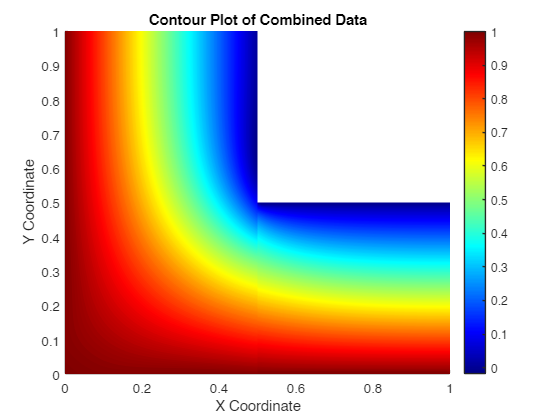

load('data_bem.mat', 'x0', 'y0', 'fieldValue');
load('data.mat', 'X_test', 'Y_test', 'U_predicted', 'dUx_predicted', 'dUy_predicted');

grid_resolution = 100;

figure; hold on;

% BEM data
x = x0(:); y = y0(:); u = fieldValue(:);
[X_grid, Y_grid] = meshgrid(linspace(min(x), max(x), grid_resolution), ...
                            linspace(min(y), max(y), grid_resolution));
U_grid = griddata(x, y, u, X_grid, Y_grid, 'cubic');
contourf(X_grid, Y_grid, U_grid, 200, 'LineColor', 'none');

% Predicted data
x = X_test(:); y = Y_test(:); u = U_predicted(:);
[X_grid, Y_grid] = meshgrid(linspace(min(x), max(x), grid_resolution), ...
                            linspace(min(y), max(y), grid_resolution));
U_grid = griddata(x, y, u, X_grid, Y_grid, 'cubic');
contourf(X_grid, Y_grid, U_grid, 200, 'LineColor', 'none');

colorbar;
colormap jet;
title('Contour Plot of Combined Data');
xlabel('X Coordinate');
ylabel('Y Coordinate');

% % Save the structure to a .mat file
% save('history_BEMPINN.mat', 'history');